# Extracción de características por tramas.

En este ejemplo, se muestra cómo extraer algunas características de una señal de audio por tramas.

A modo de ejemplo, utilizaremos la siguiente señal: 

n=1:16000;
y1=randn(1,16000); % ruido blanco
x = pinknoise(32000); % ruido rosa de 32000 muestras
% Cargamos ruido rosa que proporciona Matlab por defecto y que incorpora en memoria como x. 
y2=x(1:16000);
y3=sin(2*pi*500/8000*n); % señal tonal

% Y es la señal de entrenamiento. Contiene ruido blanco, rosa y tonal.
y=[y1 20*y2' y3+y1];
L=length(y) % muestras totales

L = 48000

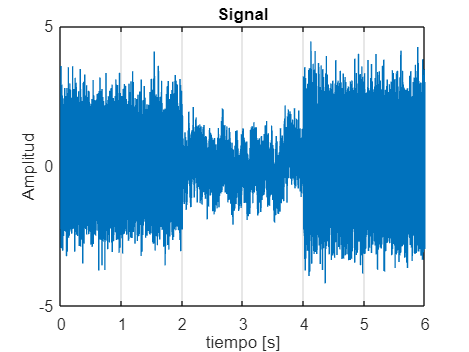

fs=8000;
tiempo=(0:L-1)/fs;
plot(tiempo,y); xlabel('tiempo [s]'); ylabel('Amplitud'); grid; 
set(gca,'FontSize',14);title('Signal');

## Características:

#### Centroide Espectral


$$SC=\frac{\sum_{k=1}^N k \cdot X(k)}{\sum_{k=1}^N X(k)}$$


*X(k) *is the amplitude of bin *k* the DFT.

ttrama=0.1;                  % Duración en segundos
ltrama= fs*ttrama;           % Longitud de la trama en muestras
Ntramas=L/ltrama;            % Número de tramas
SC=zeros(1,Ntramas);         % Centroide Espectral
tiempo_t=0:ltrama/fs:tiempo(end);  % Tiempo tramas
for ii=1:Ntramas,
    yn=st_normalize(y((ii-1)*ltrama+1:ii*ltrama));            % Normalizamos la señal
    SC(ii)=sc(yn,fs,ltrama);            % funciones de mosqito
end

plot(tiempo_t,SC);xlabel('tiempo [s]'); ylabel('Frecuencia [Hz]');
set(gca,'FontSize',14);title('Spectral Centroid'); grid; 

#### Tasa de Cruzes por cero, Zero Crossing Ratio. 

Tasa a la que la señal cambia de signo (de positivo a negativo y viceversa. Es una característica en el dominio del tiempo.

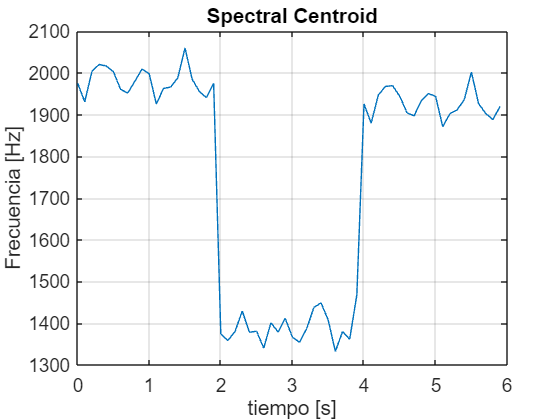

Zcr=zeros(1,Ntramas);

for ii=1:Ntramas,
    yn=st_normalize(y((ii-1)*ltrama+1:ii*ltrama));            % Normalizamos la señal
    Zcr(ii)=zcr(yn); 
end
plot(tiempo_t,Zcr);xlabel('tiempo [s]'); ylabel('Rate per frame');
set(gca,'FontSize',14);title('ZCR'); grid;

#### Energía por tramas (STE, Short Time Energy):

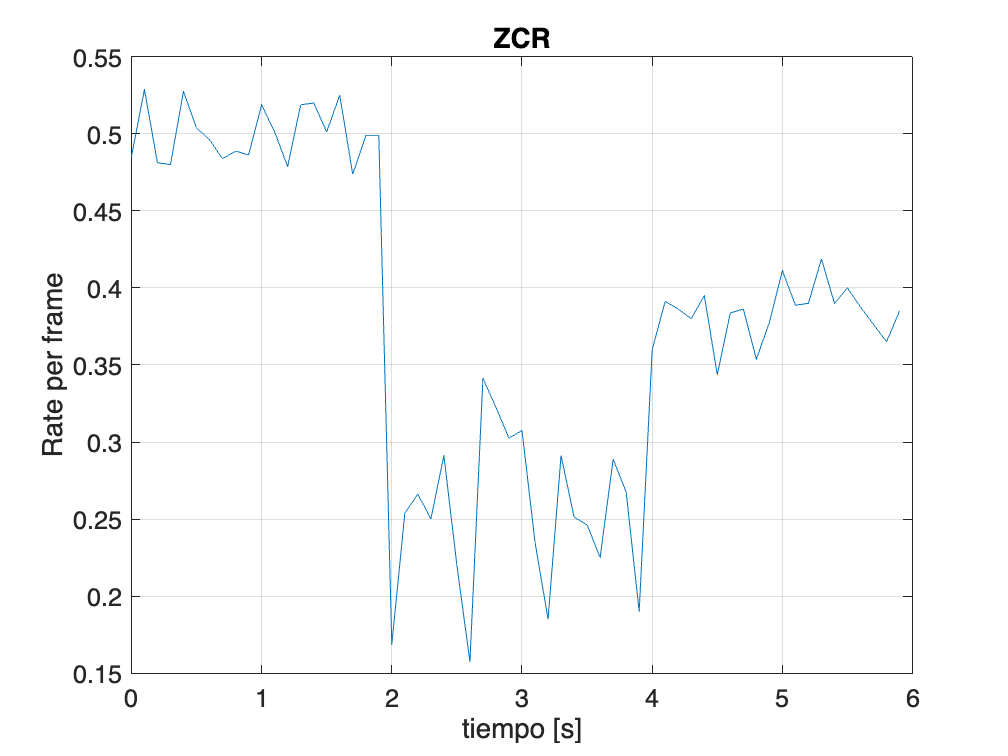

e=zeros(1,Ntramas);
for ii=1:Ntramas,
   yn=y((ii-1)*ltrama+1:ii*ltrama);            % Normalizamos la señal

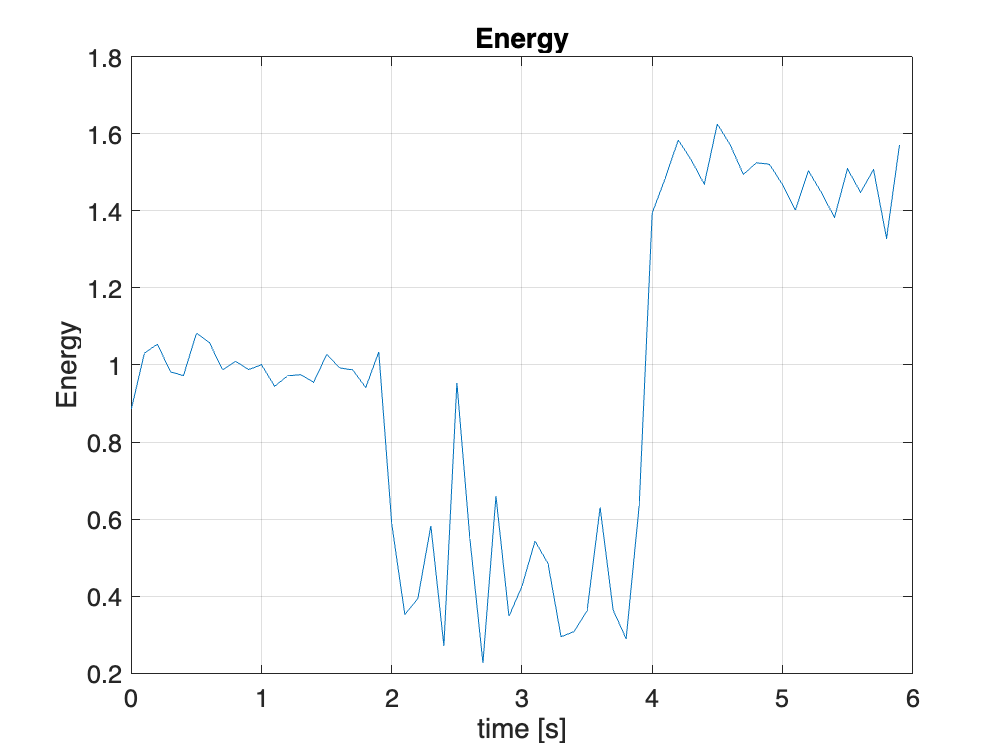

    e(ii)=sum(yn.^2)/ltrama; 
end 
plot(tiempo_t,e);xlabel('time [s]'); ylabel('Energy');
set(gca,'FontSize',14);title('Energy'); grid; 


**Kurtosis: **


$$k=\frac{E(x-\mu)^4}{\sigma^4}$$


Resulta útil para detectar la presencia de transitorios o ruido impulsivo en la señal. 

krt=zeros(1,Ntramas);
for ii=1:Ntramas,
   yn=st_normalize(y((ii-1)*ltrama+1:ii*ltrama));            % Normalizamos la señal
   krt(ii)=kurtosis(yn); 
end 
plot(tiempo_t,krt);xlabel('time [s]'); ylabel('Kurtosis');
set(gca,'FontSize',14);
grid on;

## Funciones

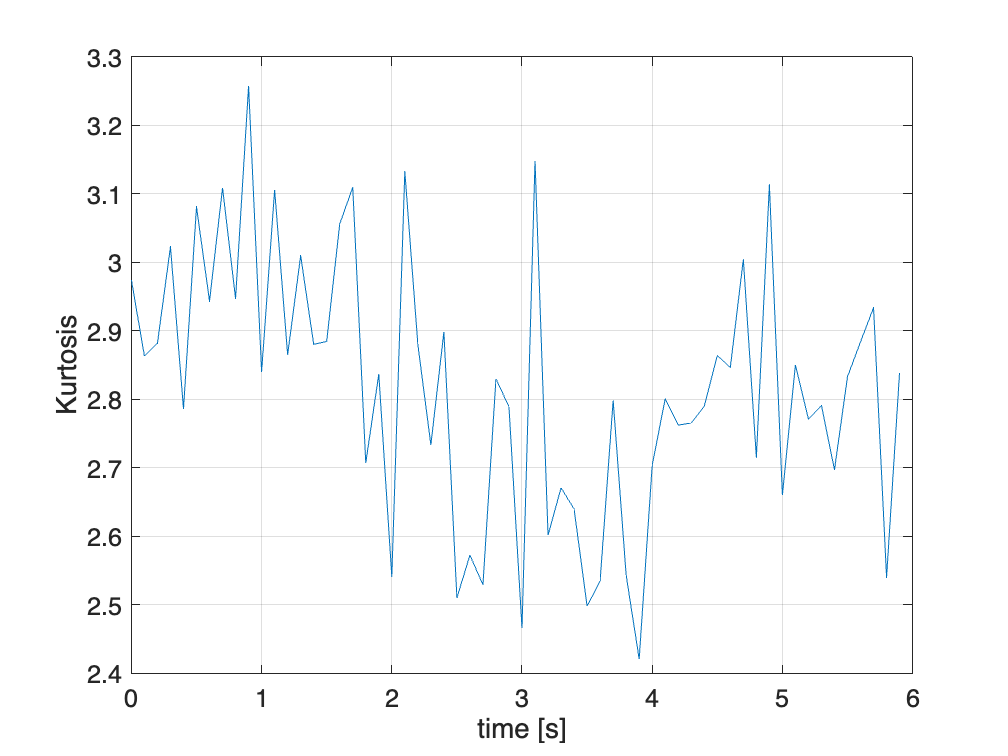

function y=sc(x,fs,N);
% Cálculo de Centroide Espectral
% x: Señal
% fs: Frecuencia de Muestreo
% N= num muestras fft.
L = length(x);

x = reshape(x,L,1);
X = abs(fft(x,N))';
f = (0:(N-1))*fs/N;
n = floor(N/2);
%Calculo sólo para la parte hasta pi del espectro
y=sum(X(1:n).*f(1:n))/sum(X(1:n));
end

function y=st_normalize(x)
y=x/std(x);
y=y-mean(y);
end

function y=zcr(x);
% Returns the Zero Crossing Ratio of a vector signal x.
% y=zcr(x);
%

L=length(x);
y =sum(abs(diff(x>0)))/L;
end
